# Exam 2020

- Optimazation And Data Analytics

- Student name: Anton Sakarias Rørbæk Sihm

- Student number: 201504954

- AU id : au535993

## Exercise 1

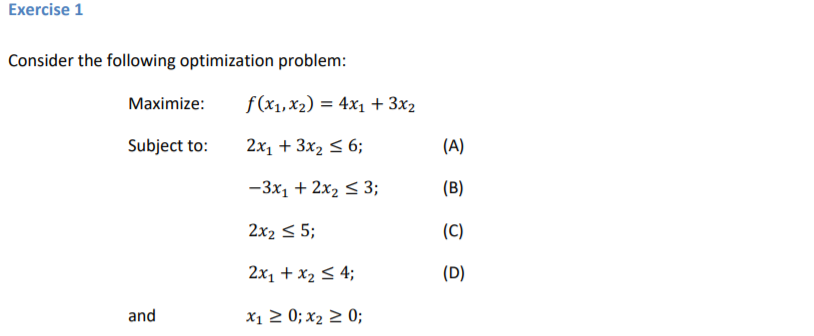

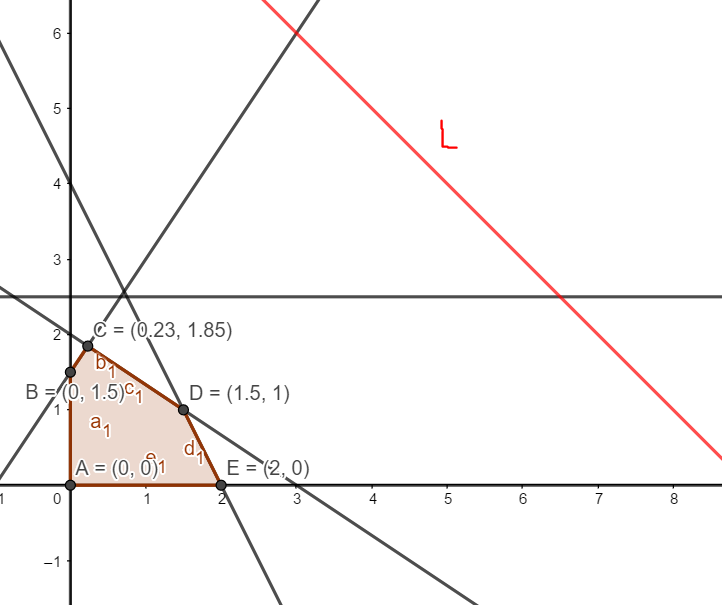

From this the get the following cadinate solutions:

pointA = [0,0];
pointB = [0,1.5];
pointC = [0.23,1.85];
pointD = [1.5,1];
pointE = [2,0];

syms x1 x2
f = 4*x1 + 3*x2;
%max pointA
x1 = pointA(1);
x2 = pointA(2);
max_A = subs(f)

$$max\_A = 0$$

%max pointB
x1 = pointB(1);
x2 = pointB(2);
max_B= double(subs(f))

max_B =        9/2     


%max pointC
x1 = pointC(1);
x2 = pointC(2);
max_C= double(subs(f))

max_C =      647/100   


%max pointD
x1 = pointD(1);
x2 = pointD(2);
max_D = double(subs(f))

max_D =        9       


%max pointE
x1 = pointE(1);
x2 = pointE(2);
max_E= double(subs(f))

max_E =        8       


fprintf("Our maxpoint is [x1, x2]  = [ %.2f, %.2f ] with max value : %.2f ", pointD, max_D );

Our maxpoint is [x1, x2]  = [ 1.50, 1.00 ] with max value : 9.00 

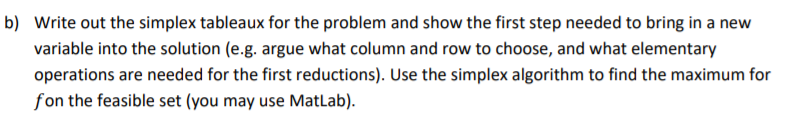

% Simplex tuable for the problem  
% Step 1 : change inquality to equality by adding slacks var and setting c to
% minus with slack var M.
%     x1   x2,    s1   s2    s3    s4    M     B  
A = [ 2,    3,    1,   0,    0,    0,    0,    6;
     -3,    2,    0,   1,    0,    0,    0,    3;
      0,    2,    0,   0,    1,    0,    0,    5;
      2,    1,    0,   0,    0,    1,    0,    4;
      -4,   -3,   0,   0,    0,    0,    1     0]

A =        2              3              1              0              0              0              0              6       
      -3              2              0              1              0              0              0              3       
       0              2              0              0              1              0              0              5       
       2              1              0              0              0              1              0              4       
      -4             -3              0              0              0              0              1              0       


% Step two: find most negative at bottom row-->  we take x1 = -4
% Step three: we will find the most positive ratio than is smallets 
% B/entry  for all entries
% 6/2 = 3  |   3/-3 = -1   | 4/2 = 2  -->  we take R4
% we will use r4 to create the pivot colum, since it makes b none negative.

% R4 *(1/2)
A(4,:) = A(4,:)*(1/2);

% R1 - 2R4
A(1,:) = A(1,:) - 2*A(4,:);

% R2 + 3R4
A(2,:) = A(2,:) + 3*A(4,:);

% R5 + 4R4
A(5,:) = A(5,:) + 4*A(4,:);

% after 1 iteration of the simplex algortihm:
A

A =        0              2              1              0              0             -1              0              2       
       0              7/2            0              1              0              3/2            0              9       
       0              2              0              0              1              0              0              5       
       1              1/2            0              0              0              1/2            0              2       
       0             -1              0              0              0              2              1              8       


clear x1 x2
% This is the first iteration
% lets finish the rest computationally
x1 = optimvar('x1');
x2 = optimvar('x2');

prob = optimproblem('Objective', 4*x1 +3*x2,'ObjectiveSense','max');
prob.Constraints.c1 = 2*x1 + 3*x2  <= 6;
prob.Constraints.c2 = -3*x1 + 2*x2  <= 3;
prob.Constraints.c3 = 2*x2 <= 5;
prob.Constraints.c4 = 2*x1 + x2 <= 4;
prob.Constraints.c5 = x2 >= 0;
prob.Constraints.c5 = x1 >= 0;

problem = prob2struct(prob);
[sol,fval,exitflag,output] = linprog(problem);

Optimal solution found.



max_value = 4*sol(1) + 3*sol(2);
fprintf("Our maxpoint is [x1, x2]  = [ %.2f,  %.2f] with max value : %.2f ", sol, max_value );

Our maxpoint is [x1, x2]  = [ 1.50,  1.00] with max value : 9.00 

% we can indeed conclude that this is the same as found via the geografic
% method in 2d.

% lets compute then final simplix tablue:
matrix=[1 0 0 1 0 0;
        4 1 0 0 1 0; 
        8 4 1 0 0 1];

b=[1;4;16];
c=-[4;2;1;0;0;0];
v=[4;5;6];

matrix=[ 2  3  1  0  0  0;
        -3  2  0  1  0  0; 
         0  2  0  0  1  0;
         2  1  0  0  0  1];

b=[6;3;5;4];
c=-[4;3;0;0;0;0];
v=[3;4;5;6];

simplex(c,matrix,b,v,1)

 
Initial tableau:
       2              3              1              0              0              0              6       
      -3              2              0              1              0              0              3       
       0              2              0              0              1              0              5       
       2              1              0              0              0              1              4       
      -4             -3              0              0              0              0              0       

Pivot point:
       4              1       

New tableau:
       0              2              1              0              0             -1              2       
       0              7/2            0              1              0              3/2            9       
       0              2              0              0              1              0              5       
       1              1/2            0              0              0      

ans =        3/2     
       1       
       0       
      11/2     
       3       
       0       


% At the final tablue we can see the solution the the dual problem as well. Which
% is the marginal values : A = 1/2    B = 0    C = 0    D = 3/2
% This is the input values for the dual problem, that gives the minimize
% solution.

% Since the inequallity C has no contribution to the maximum point we can
% acutally set it to infinite with changing the maximum point.

## Exercise 2

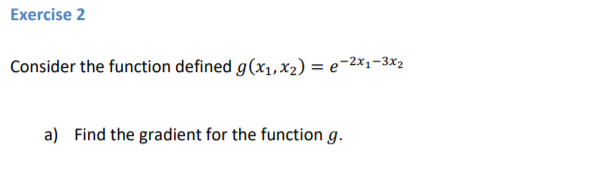

clearvars;
warning('off');
syms x1 x2
g = exp(1)^(-2*x1-3*x2);

% parciel diff for x1 for first index of the gradient.
% parciel diff for x2 for second index of the gradient.

gradiant_g = gradient(g, [x1, x2])

$$gradiant\_g = \left(\begin{array}{c} -2\,\frac{1}{{\left(\frac{3060513257434037}{1125899906842624}\right)}^{2\,x_{1}+3\,x_{2}}}\,\log\left(\frac{3060513257434037}{1125899906842624}\right)\\ -3\,\frac{1}{{\left(\frac{3060513257434037}{1125899906842624}\right)}^{2\,x_{1}+3\,x_{2}}}\,\log\left(\frac{3060513257434037}{1125899906842624}\right) \end{array}\right)$$

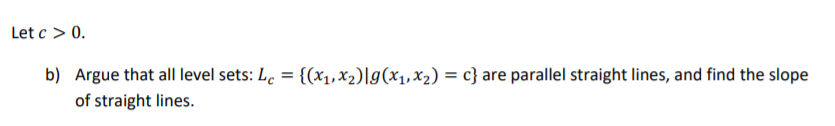

% function g plotted.

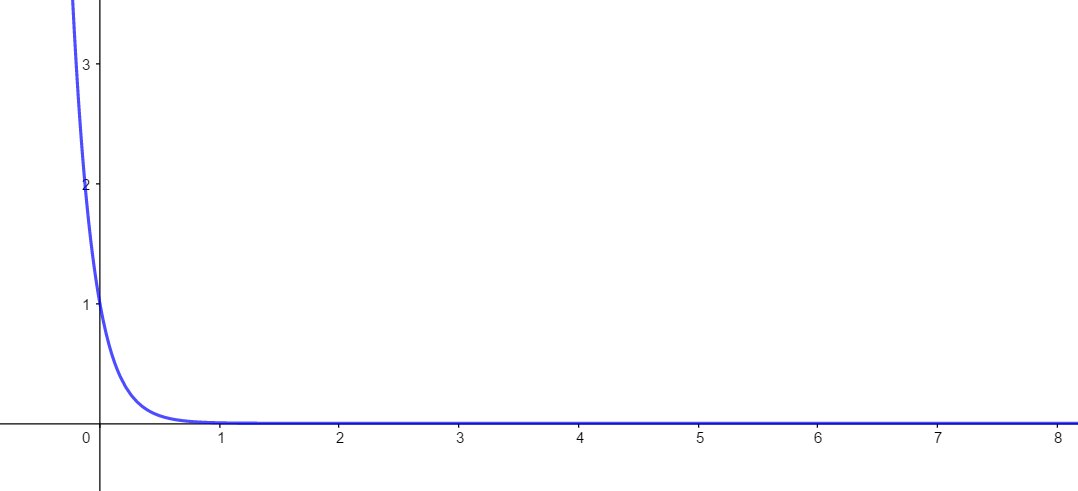

% When c > 0 we will have straight line in g, and the lvl set will be
% paralel.

% We can differentiate the function to get a function for the slope.
% for c> 0 this will be 0 for the lvl set and the function g.

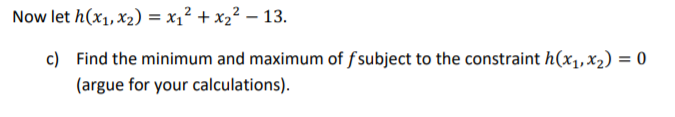

We will use the Lagrange multiplier for the problem


$$\nabla f\left(x\right)+\lambda *\nabla h\left(x\right)=0$$
 

We can solve the follwing problem by solving 3 linequeations with 3 uknowns

% I Assume that the f  function is meant to be g?????? I will ref to
% function g as f
clearvars
syms x1 x2
f = exp(1)^(-2*x1-3*x2);
gradiant_f = gradient(f, [x1,x2])

$$gradiant\_f = \left(\begin{array}{c} -2\,\frac{1}{{\left(\frac{3060513257434037}{1125899906842624}\right)}^{2\,x_{1}+3\,x_{2}}}\,\log\left(\frac{3060513257434037}{1125899906842624}\right)\\ -3\,\frac{1}{{\left(\frac{3060513257434037}{1125899906842624}\right)}^{2\,x_{1}+3\,x_{2}}}\,\log\left(\frac{3060513257434037}{1125899906842624}\right) \end{array}\right)$$

clear x1 x2
syms x1 x2 lambda

h = x1^2 + x2^2 -13;
gradiant_h = gradient(h, [x1,x2])

$$gradiant\_h = \left(\begin{array}{c} 2\,x_{1}\\ 2\,x_{2} \end{array}\right)$$

% Lagrange multiplier
Lagrange_multiplier = gradiant_f + lambda*gradiant_h == 0

$$Lagrange\_multiplier = \left(\begin{array}{c} 2\,\lambda \,x_{1}-2\,\frac{1}{{\left(\frac{3060513257434037}{1125899906842624}\right)}^{2\,x_{1}+3\,x_{2}}}\,\log\left(\frac{3060513257434037}{1125899906842624}\right)=0\\ 2\,\lambda \,x_{2}-3\,\frac{1}{{\left(\frac{3060513257434037}{1125899906842624}\right)}^{2\,x_{1}+3\,x_{2}}}\,\log\left(\frac{3060513257434037}{1125899906842624}\right)=0 \end{array}\right)$$

% we now have 2 equation and 3 unknowns
% we can use the fuction h = 0 as the last one:
equation1 = Lagrange_multiplier(1)

$$equation1 = 2\,\lambda \,x_{1}-2\,\frac{1}{{\left(\frac{3060513257434037}{1125899906842624}\right)}^{2\,x_{1}+3\,x_{2}}}\,\log\left(\frac{3060513257434037}{1125899906842624}\right)=0$$

equation2 = Lagrange_multiplier(2)

$$equation2 = 2\,\lambda \,x_{2}-3\,\frac{1}{{\left(\frac{3060513257434037}{1125899906842624}\right)}^{2\,x_{1}+3\,x_{2}}}\,\log\left(\frac{3060513257434037}{1125899906842624}\right)=0$$

equation3 =  x1^2 + x2^2 -13 == 0

$$equation3 = {x_{1}}^{2}+{x_{2}}^{2}-13=0$$

[x1,x2,lambda] = solve([equation1, equation2, equation3], [x1,x2, lambda]);
x1 = double(x1)

x1 =        2       


x2 = double(x2)

x2 =        3       


lambda = double(lambda)

lambda =        1/884827


% candidate coordinates 
s1 = [x1(1), x2(1)];
% Solutions
%(x1-2)^2 + (x2-1)^2;
f1 = exp(1)^(-2*s1(1)-3*s1(2));
fprintf("maximum: %.2f at point : (%.2f, %.2f)", f1, s1);

maximum: 0.00 at point : (2.00, 3.00)

## Exercise 3

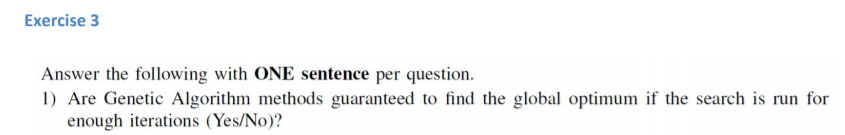

% Even tho we run for long enough, we will have higher probalitity. But we
% cannot corfirm that we will find the global optimum. 
% NO.

% Stocastic means that the algortihm have some randomness included.
% The generic method is stochastic. When candidate solutions have at high
% fitness, the highere probalilyty there are for some to spawn childrin, by
% doing crossovers.

% 1. Candidate solutions are represented by chromosomes
% 2. uses Exploration or explortation to explore new solutions
% 3. Fitness funtion decides how good a  chromosome is
% 4. 2 Chrosomes have to possibility to spawn childrin if thier fitness is
% high.

% 1. When the error is acceptable. Neuton method: one could be that with
% the results does not change decimals after 5 decimals we converge.
% 2. Number of interations. When we have limited computational power, we
% might be satisfied at some interation.

% 1. Golden seach method, for find local minimum between two points (No differential needed)
% 2. Steepest decent method for finden local minimum differential needed
% 3. Swarm optimazation for finding local/global optimums
% 4. Simulated anealing for finding local/global optimums 
% 5. Neuton method for finding local/global optimums

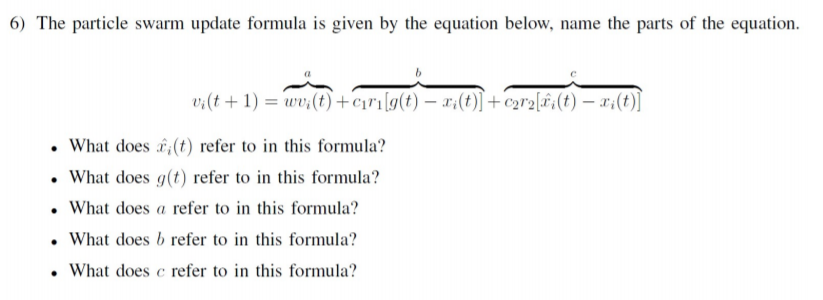

% 1. 
% - Best position for current particle v_i up to iteration t

% 2.
% - Best position so far from any particale (GLOBAL BEST)

% 3 a.
% -inertia component: keeps particle moving in similar direction 
% - Velocity of current particale v_i at iteration t is included  

% 4 b.
% - social component: encourages particle to move to swarms best found
% position so far: g(t)

% 5 c.
% -cognitive component: current particle memory, encourages particle to go back to best position 

## Exercise 4

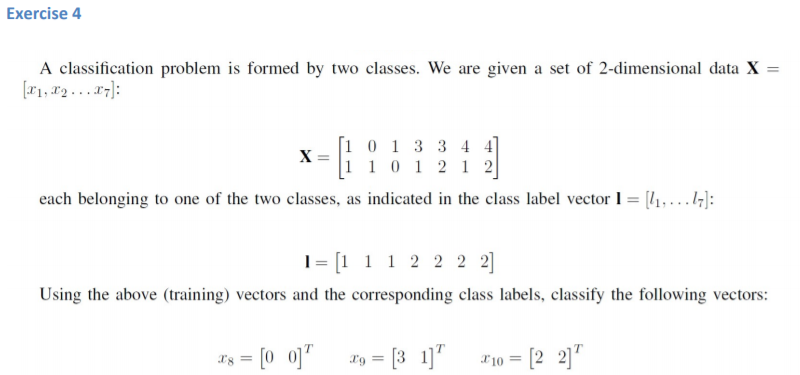

%For this I will use python.

I did the following in python. Th steps are as follows:

% Calculate the centroid for each class --> mean each x_i of each class
% Calculate the dist from test sample to each centroid
% Classify by taking the smallest dist to centroid.
% The python code can be seen as follows:

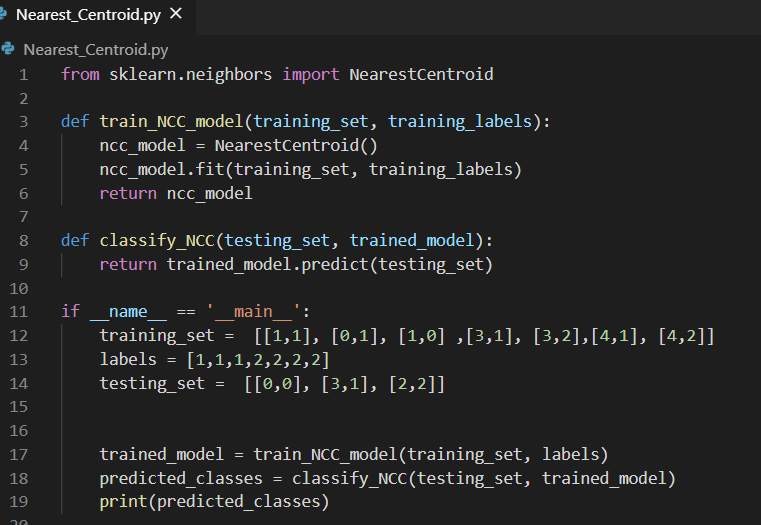

%  .\Nearest_Centroid.py  yields the prediction for x_i for i = 8, 9, 10.
%  prediction =  [1 2 2]

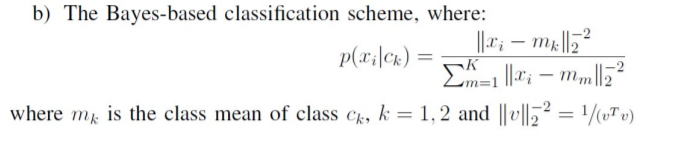

% For this i will use python, with the following code:

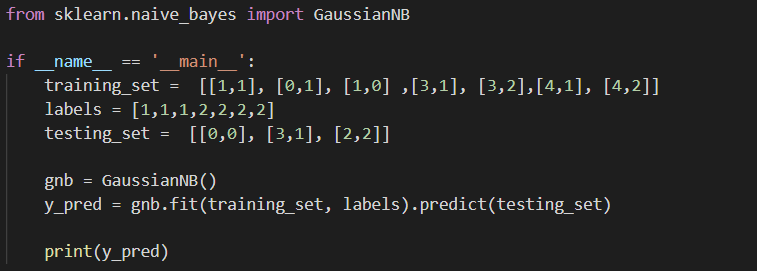

%.\Bayes_classification_scheme.py yields the following prediction : [1 2 2]

## Exercise 5

% - Since the inputs are in R5 we will input to have an input of 5 neurons
% - I have chosen the 2 hidden layer size 3 randomly. But normaly this
% heavyly depends on the input problem.
% - Then we have the output layer, which consist of 3 different out clases
% - We have the bias, the shift the activation funtion from left to right.

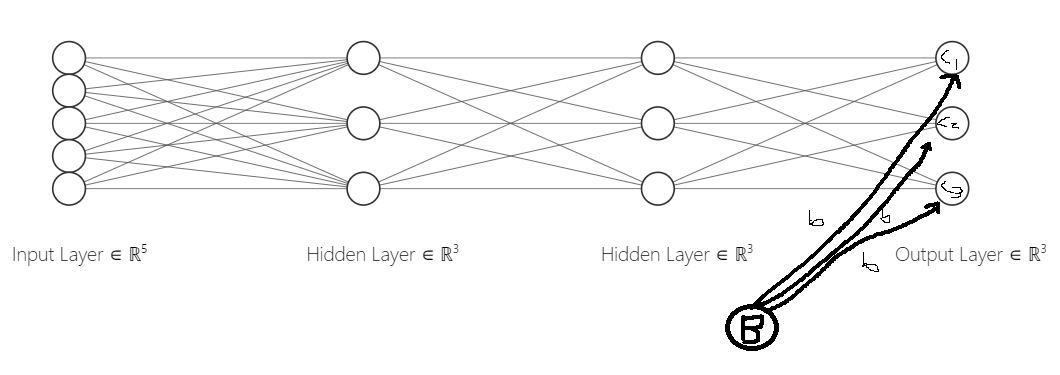

% BLANK

% We should initilize random in the normilized space

## Exercise 6

#   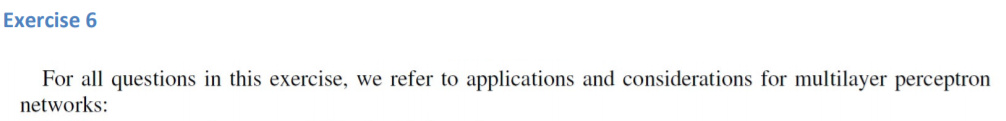

% Since we are using the stochastic approch, the network will learn much
% faster.

% Input generated input samples can exploit this, giving feeding the
% network multiple random samples.

% The actvation functions typically works with values around -1 to 1. This
% also makes the neural network much fast.

% When we have big network, and want to train it fast.

% This means that the trained model is not fittet enough to do testing.
% This is caused by that the model cant find any relationship between the input samples. 

% 1. train with data that the algorithm should be avalble to classify
% 2. train with subsets of classes of data that the algorithm should be availble to classify
% 3. train with data that the algorithm should not be able to classify, so
% that it can learn from mistakes.
% - Supervises learned can affect it, be manuely correct the network when
% doing mistakes or doing the correct.

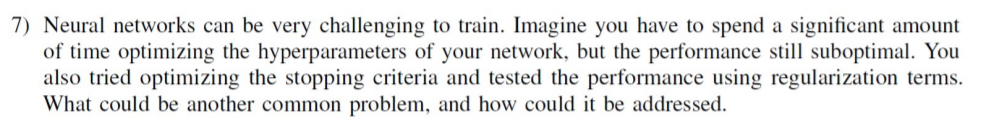

%Blank